%% ===============================================================
%  STEP 2 - Curva estática PWM–Presión (solo PWM >= PWM_MIN)
%  Archivo: analisis_bomba_step2_estatica.m
%
%  Objetivo:
%    - Detectar escalones de PWM en el experimento
%    - Calcular la presión "en régimen" para cada escalón
%    - Construir la curva estática PWM–Presión
%    - Usar solo la zona de interés: PWM >= PWM_MIN
% ================================================================

clear; clc; close all;

%% 1) CONFIGURACIÓN
nombreArchivo       = 'datos_barrido_Com_N.csv';   % mismo archivo del step1
numMuestrasPromedio = 25;    % nº de muestras para promediar al final del escalón
PWM_MIN             = 120;   % solo analizamos escalones con PWM >= 120

%% 2) CARGAR DATOS
data   = readtable(nombreArchivo);
t_ms   = data.t_ms;
u_pwm  = data.PWM;
p_kPa  = data.Presion_kPa;
t_s    = t_ms / 1000.0;

%% 3) DETECCIÓN DE ESCALONES EN PWM
% Un escalón nuevo ocurre cuando PWM cambia de valor
idxCambios = find(diff(u_pwm) ~= 0);   % índices donde cambia el PWM
% Los límites de los tramos son:
%   1 (inicio), idxCambios+1 (inicios internos), length(u_pwm)+1 (fin)
idxInicio = [1; idxCambios + 1];
idxFin    = [idxCambios; length(u_pwm)];

nTramos = numel(idxInicio);
fprintf('Se detectaron %d tramos de PWM constante.\n', nTramos);

Se detectaron 53 tramos de PWM constante.



%% 4) RECORRER CADA TRAMO Y CALCULAR PRESIÓN EN RÉGIMEN
PWM_lista      = [];
Pmedia_lista   = [];
Pstd_lista     = [];
tRepresentativa = [];

for k = 1:nTramos
    i1 = idxInicio(k);
    i2 = idxFin(k);

    pwm_tramo = u_pwm(i1:i2);
    pres_tramo = p_kPa(i1:i2);
    t_tramo    = t_s(i1:i2);

    % Valor del PWM en este tramo (debería ser constante)
    pwm_val = pwm_tramo(1);

    % Filtrar por zona de interés
    if pwm_val < PWM_MIN
        continue;   % ignoramos este escalón
    end

    % Elegir la "cola" del tramo para promediar (régimen)
    L = numel(pres_tramo);
    N = min(numMuestrasPromedio, L);   % por si el tramo es muy corto

    idxTail = L-N+1 : L;
    pres_tail = pres_tramo(idxTail);

    p_mean = mean(pres_tail);
    p_std  = std(pres_tail);
    t_rep  = mean(t_tramo(idxTail));

    PWM_lista        = [PWM_lista; pwm_val];
    Pmedia_lista     = [Pmedia_lista; p_mean];
    Pstd_lista       = [Pstd_lista; p_std];
    tRepresentativa  = [tRepresentativa; t_rep];
end

fprintf('Se obtuvieron %d escalones en la zona PWM >= %d.\n', ...
        numel(PWM_lista), PWM_MIN);

Se obtuvieron 28 escalones en la zona PWM >= 120.


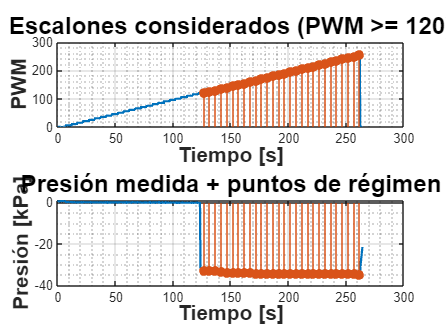


if isempty(PWM_lista)
    warning('No se encontraron tramos con PWM >= PWM_MIN. Revisa PWM_MIN.');
    return;
end

%% 5) ORDENAR POR NIVEL DE PWM (por estética de la curva)
[ PWM_ordenado, idxSort ] = sort(PWM_lista);
Pmedia_ordenada = Pmedia_lista(idxSort);
Pstd_ordenada   = Pstd_lista(idxSort);

%% 6) GRÁFICAS: VALIDACIÓN EN TIEMPO + CURVA ESTÁTICA

LW   = 2.0;
FS   = 14;
FSbig = 16;
morado = [0.4 0 0.8];

% --- 6.1 Gráfica de validación: señal original + puntos de régimen ---
figure('Name','Validación de escalones en régimen','Color','w');

subplot(2,1,1);
plot(t_s, u_pwm, 'LineWidth', 1.5); hold on;
stem(tRepresentativa, PWM_lista, 'filled');
grid on; grid minor;
xlabel('Tiempo [s]', 'FontSize', FS, 'FontWeight','bold');
ylabel('PWM', 'FontSize', FS, 'FontWeight','bold');
title(sprintf('Escalones considerados (PWM >= %d)', PWM_MIN), ...
      'FontSize', FSbig, 'FontWeight','bold');

subplot(2,1,2);
plot(t_s, p_kPa, 'LineWidth', 1.5); hold on;
stem(tRepresentativa, Pmedia_lista, 'filled');
grid on; grid minor;
xlabel('Tiempo [s]', 'FontSize', FS, 'FontWeight','bold');
ylabel('Presión [kPa]', 'FontSize', FS, 'FontWeight','bold');
title('Presión medida + puntos de régimen', ...
      'FontSize', FSbig, 'FontWeight','bold');

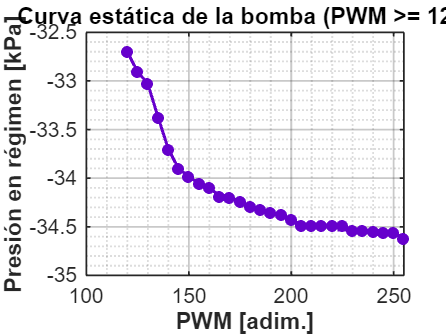


% --- 6.2 Curva estática PWM–Presión ---
figure('Name','Curva estatica PWM-Presion','Color','w');

errorbar(PWM_ordenado, Pmedia_ordenada, Pstd_ordenada, ...
         '-o', 'LineWidth', LW, 'MarkerSize', 6, 'Color', morado, ...
         'MarkerFaceColor', morado);
grid on; grid minor;
xlabel('PWM [adim.]', 'FontSize', FS, 'FontWeight','bold');
ylabel('Presión en régimen [kPa]', 'FontSize', FS, 'FontWeight','bold');
title(sprintf('Curva estática de la bomba (PWM >= %d)', PWM_MIN), ...
      'FontSize', FSbig, 'FontWeight','bold');

ax = gca;
ax.FontSize = FS;
ax.LineWidth = 1.2;
ax.GridAlpha = 0.25;
ax.MinorGridAlpha = 0.15;

ax.Box = 'on';

%% 7) OPCIONAL: GUARDAR FIGURAS
% print('fig_validacion_escalones','-dpng','-r300');
% print('fig_curva_estatica_PWM_presion','-dpng','-r300');
